# ACO Assignment 2022 Q4 Mixed Sensitivity Controller

## Load Linearized State-space plant

clc 
clear 
load linearizedModel_Outputs.mat
 %#ok<*NOPTS>

## Define some variables for use

s = zpk('s') %for defining transfer functions

s =
 
  s
 
Continuous-time zero/pole/gain model.



om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(12,17,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 10*0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz

bw_gamma_rad = 12.5664

bw_alpha_rad = 10*0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz

bw_alpha_rad = 15.7080

    
ny = 2; %define the output dimension, for identity matrices    
THE_AXES = [-110 30];


## Design some ideal responses

T_gamma_ideal = bw_gamma_rad / (s+bw_gamma_rad);
S_gamma_ideal = s/(s+bw_gamma_rad)

S_gamma_ideal =
 
      s
  ---------
  (s+12.57)
 
Continuous-time zero/pole/gain model.





T_alpha_ideal = bw_alpha_rad / (s+bw_alpha_rad);
% S_alpha_ideal = s/(s+bw_alpha_rad);% Set 1
S_alpha_ideal = s/(s+1e3*bw_alpha_rad);% Set 2

controlWeighting = 0.1;%Set 1: 0.1 Set 2: 0.5

CS_gamma_ideal = controlWeighting*10*bw_gamma_rad/(0.1*s+bw_gamma_rad);
% CS_alpha_ideal = controlWeighting*10*bw_alpha_rad/(0.1*s+bw_alpha_rad); %Set 1
CS_alpha_ideal = controlWeighting*1*bw_alpha_rad/(0.1*s+bw_alpha_rad); %Set 2
% Put the weights together
S_ideal = mdiag(S_gamma_ideal,S_alpha_ideal);
T_ideal = mdiag(T_gamma_ideal,T_alpha_ideal);

CS_ideal = mdiag(CS_gamma_ideal,CS_alpha_ideal);

% figure(1)
% clf
% bodemag(S_ideal, 'k-', T_ideal, 'b-', CS_ideal, 'k--', om_rad);
% legend('S\_ideal', 'T\_ideal', 'CS\_ideal', 'Location', 'southeast');
% grid on

## Adjust weights to make them realizable

%Make Realizable T
epsilon = 1e-6; %define what is "small", 1e-3 was too large and cannot mitigate control signal nosie

T_realizable = T_ideal * tf([epsilon 1],[0 1]);

%Make Realizable S
[num, den] = tfdata(S_ideal, 'v');

num{1,1}(1,2) = epsilon;
num{end,2}(1,2) = epsilon;
S_realizable = tf(num,den);

CS_realizable = CS_ideal* tf([epsilon 1],[0 1]);

% figure(1)
% clf
% bodemag(S_realizable, 'k-', T_realizable, 'b-', CS_realizable, 'k--', ...
%     om_rad);
% legend('S\_realizable', 'T\_realizable', 'CS\_realizable', ...
%     'Location', 'southeast');
% grid on

## Design the weights individually then combine them

Ws_tf = 1/ S_realizable

Ws_tf =
 
  From input 1 to output...
       s + 12.57
   1:  ---------
       s + 1e-06
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       s + 1.571e04
   2:  ------------
        s + 1e-06
 
Continuous-time transfer function.



Wu_tf = 1/ CS_realizable

Wu_tf =
 
  From input 1 to output...
       7957.7 (s+125.7)
   1:  ----------------
           (s+1e06)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       63662 (s+157.1)
   2:  ---------------
          (s+1e06)
 
Continuous-time zero/pole/gain model.



Wt_tf = 1/ T_realizable

Wt_tf =
 
  From input 1 to output...
       79577 (s+12.57)
   1:  ---------------
          (s+1e06)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       63662 (s+15.71)
   2:  ---------------
          (s+1e06)
 
Continuous-time zero/pole/gain model.




%Convert to state-space

Ws = ss(Ws_tf);
Wu = ss(Wu_tf);
Wt = ss(Wt_tf); 


## Form the augmented Plant and controller

Paug = augw(P_ss_self,Ws,Wu,Wt);
[C, ~, gam] = hinfsyn(Paug);
% C = -ncfsyn(Paug);

C = minreal(C);

3 states removed.


C = balreal(C);


## Find the close loop responses and sensitivity

Lmix = P_ss_self*C;
% Lmix1 = Lmix; %Set 1
Lmix2 = Lmix; %Set 2
T = feedback(Lmix,eye(ny));
S = eye(ny)-T;
CS = feedback(C, P_ss_self);


## Plot S, T and bodemag

figure(2)
clf
subplot(121)
sigma(P_ss_self, Paug,Lmix,om_rad)
% sigma(P_ss_self, Paug,Lmix,om_rad_lin)
legend ('Linear Plant', 'Augmented Plant', 'Close Loop')
grid on

sp2b= subplot(222);
bodemag(S, 'k-', T, 'b-', CS, 'k--', om_rad);
legend('S', 'T', 'CS', 'Location', 'southwest');
ylim(sp2b, THE_AXES)
ylim(THE_AXES)
grid on

subplot(224)
step(T, 'b-', 0.8)
grid on


## Plot S, T, CS bodemag and combinedweight

    figure(3)
    clf
    sp3a = subplot(231);
    bodemag(S_ideal, S, om_rad);
    legend('location','northeast')
    ylim(sp3a, THE_AXES)
    ylim(THE_AXES)
    legend
    grid on
    
    sp3b = subplot(232);
    bodemag(CS_ideal, CS, om_rad);
    ylim(sp3b, THE_AXES)
    ylim(THE_AXES)
    legend
    grid on
    
    sp3c = subplot(233);
    bodemag(T_ideal, T, om_rad);
    ylim(sp3c, THE_AXES)
    ylim(THE_AXES)
    legend
    grid on
    
    subplot(212)
    % CombinedWeight = lft(Paug, C);
    sigma(Ws*S, Wu*CS, Wt*T,Lmix,om_rad)
    legend ('Ws*S', 'Wu*CS', 'Wt*T', 'Close Loop','location','southwest')
    % sigma(CombinedWeight, Lmix, om_rad);
    % legend('Combined Weight')
    grid on

## Check robustness with multiloop input output diskmargin

[~,MM_P] = diskmargin(P_ss_self)
% DGM_P_alpha = DM_P(2).GainMargin;
% DGM_P_gamma = DM_P(1).GainMargin;

% DGMAll_P = [DGM_P_gamma;DGM_P_alpha];
DGM_P = MM_P.GainMargin;

% Not applicable to Paug, since it is not square matrix
% [~,MM_Paug] = diskmargin(Paug)
% DGM_Pw_alpha = DM_Pw(2).GainMargin
% DGM_Pw_gamma = DM_Pw(1).GainMargin

% % DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha];
% DGM_Paug = MM_Paug.GainMargin;

[~,MM_Lmix1] = diskmargin(Lmix1)

DGM_Lmix1 = MM_Lmix1.GainMargin;

[~,MM_Lmix2] = diskmargin(Lmix2)

DGM_Lmix2 = MM_Lmix2.GainMargin;

## Plot the diskmargins

figure(6)
clf
t6 = tiledlayout(1,3,'TileSpacing','None',"Padding","Compact");
ax6a = nexttile
diskmarginplot(DGM_P,'disk')

ax6b = nexttile
diskmarginplot(DGM_Lmix1,'disk')
linkaxes([ax6a,ax6b],'x')

ax6c = nexttile
diskmarginplot(DGM_Lmix2,'disk')
ylim([-1.5 1.5]) %Set 1
linkaxes([ax6a,ax6b,ax6c],'x')
linkaxes([ax6a,ax6b,ax6c],'y')
% 
t6title = {'Multiloop I/O Disk Margin','Left: Linear Plant, Middle: Robustified Loop (Set 1), Right: Robustified Loop (Set 2)'};
% 
% title(t6,{t6title})
title(t6,t6title)

%% 
% figure(7)
% clf
% t = tiledlayout(2,2,'TileSpacing','Compact');
% 
% nexttile
% diskmarginplot(DGM_P_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_P_alpha,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_alpha,'nyquist')
% title(t,{'Disk Margin for robustness within region of uncertainty','First Column: Azimuth Voltage to '})

## Plotting the sigma, S and T Responses

figure(9)
clf

subplot(121)
sigma(P_ss_self, 'm-.', Paug, 'k--', Lmix, 'b-', om_rad);
% ylim(THE_AXES)
tweakAxes;
legend('P', 'Final Paug', 'Lmix', 'Location', 'northeast')

sp9b = subplot(222)
ylim(THE_AXES)  
bodemag(S, 'k-', T, 'b-', CS, 'k:', om_rad);
legend
% tweakAxes;
% ylim(THE_AXES)
 ylim(sp9b, THE_AXES)
 ylim(THE_AXES)
 grid on


subplot(224)
step(T,1);
legend
grid on

## Check the robustness with rho, v-gap

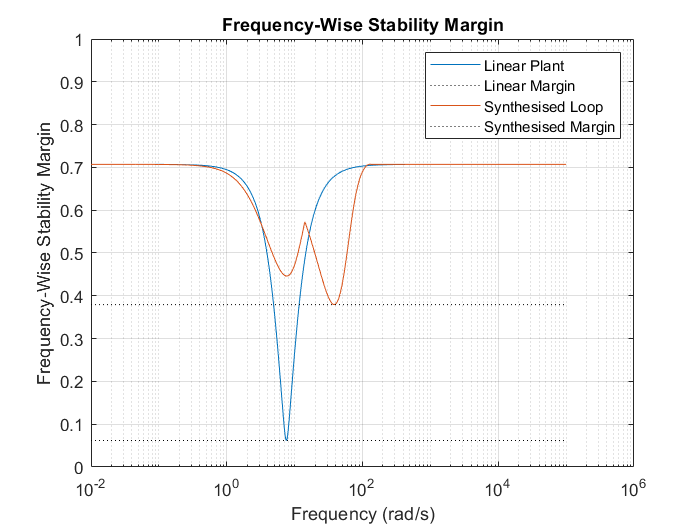

figure(5)
clf
rho(P_ss_self, -eye(ny),om_rad)
hold on
rho(Lmix, -eye(ny),om_rad)
grid on
legend('Linear Plant','Linear Margin','Synthesised Loop','Synthesised Margin')
hold off


[~,bPC] = rho(P_ss_self, -eye(ny)) %bPC = 0.0620

bPC = 0.0620

[~,bLmix] = rho(Lmix, -eye(ny)) %bLmix = 0.2690

bLmix = 0.3795